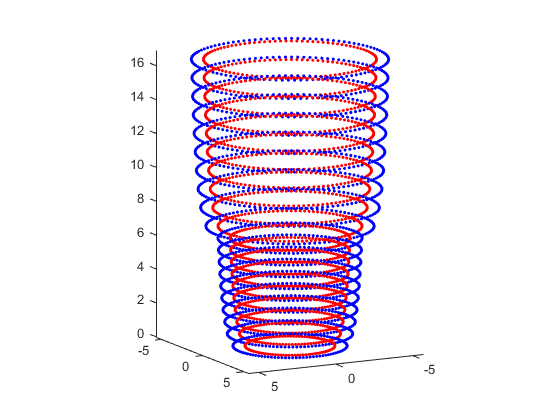

n = 10;
intervalo1 = linspace(0,7.06037512,n+1);
intervalo2 = linspace(7.06037512,18,n+1);
paso1 = intervalo1(2) - intervalo1(1);
paso2 = intervalo2(2) - intervalo2(1);
volumen1 = 0;
volumen2 = 0;
volumen1_contorno = 0;
volumen2_contorno = 0;
for Z =1:n
    radio1 = log((intervalo1(Z)+intervalo1(Z+1))/2)/ log(30) + 2.9;
    radio2 = log((intervalo2(Z)+intervalo2(Z+1))/2 - 7)/ log(30) + 4.3;
    area1 = pi*radio1^2;
    area2 = pi*radio2^2;
    volumen1 = volumen1 + area1 * paso1;
    volumen2 = volumen2 + area2 * paso2;
    
    radio1_contorno = radio1 + 0.7;
    radio2_contorno = radio2 + 0.7;
    area1_contorno = pi * radio1_contorno^2;
    area2_contorno = pi * radio2_contorno^2;
    volumen1_contorno = volumen1_contorno + area1_contorno * paso1;
    volumen2_contorno = volumen2_contorno + area2_contorno * paso1;
    theta = 0;
    while theta <= 2*pi
        A = [cos(theta) -sin(theta) 0;
        sin(theta) cos(theta) 0;
        0 0 1];
        
        B = A * [radio1; 0; intervalo1(Z)]; %matriz para rotacion con vector
        x1=B(1,1);
        y1=B(2,1);
        z1=B(3,1);
        plot3(x1,y1,z1,'.r')
        
        C = A * [radio2; 0; intervalo2(Z)];
        x2=C(1,1);
        y2=C(2,1);
        z2=C(3,1);
        plot3(x2,y2,z2,'.r')
        
        D = A * [radio1_contorno; 0; intervalo1(Z)];
        x1_c=D(1,1);
        y1_c=D(2,1);
        z1_c=D(3,1);
        plot3(x1_c,y1_c,z1_c,'.b')
        
        E = A * [radio2_contorno; 0; intervalo2(Z)];
        x2_c=E(1,1);
        y2_c=E(2,1);
        z2_c=E(3,1);
        plot3(x2_c,y2_c,z2_c,'.b')
        hold on
        theta = theta + pi/50;
        axis equal
    end
end
hold off;

volumen1

volumen1 = 227.2639

volumen2

volumen2 = 769.7755

material = volumen1 + volumen2

material = 997.0395


material2 = volumen1_contorno + volumen2_contorno

material2 = 0


materialtotal = material2 - material

materialtotal = -997.0395